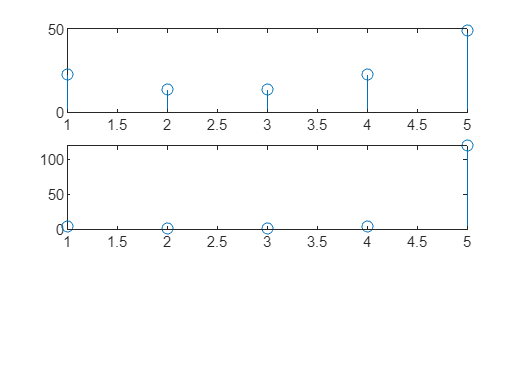

%CONVOLUTION

x= [1 2 3 4 5 ];
y= [6 7 8 9 10 ];

N= length(x);

c= conv(x,y);
LHS= DTFS(c,N);

an= DTFS(x,N);
bn= DTFS(y,N);

RHS= N*an.*bn;

subplot(3,1,1)
stem(abs(LHS))

subplot(3,1,2)
stem(abs(RHS))